## **Symbolic Math** **in ****Matlab**

## Objectives

- Go over the fundamental operations of symbolic math in matlab

- Understand the differences between numerical analysis and symbolic math in MATLAB

## Materials:

introtosymbolicmath.mlx

twonodes_primer.mlx

## Homework:

hw3.symbolicmath1.doc

hw3.symbolicmath2.doc

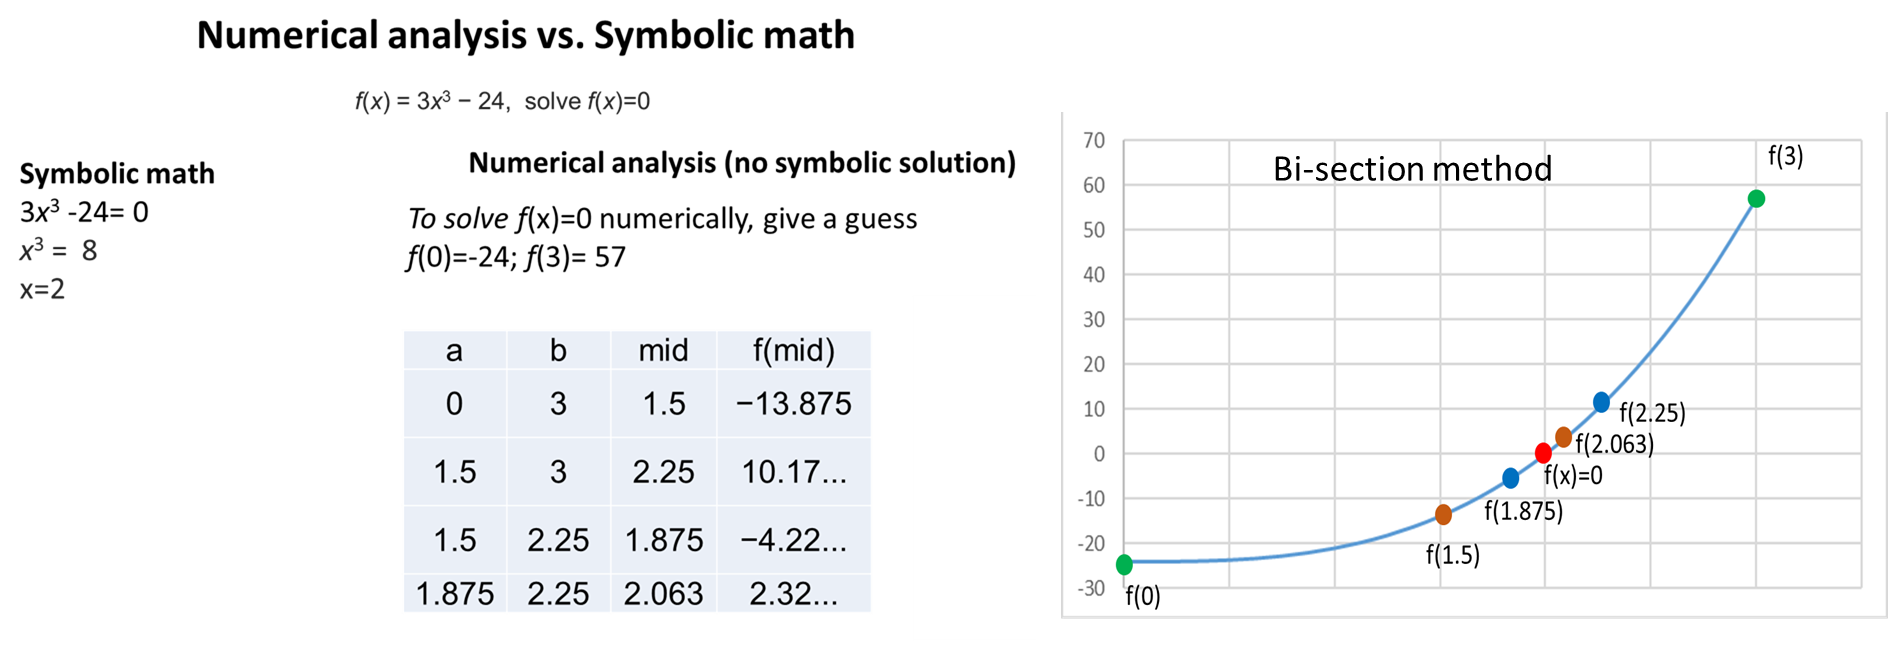

## **Introduction to Symbolic Math. **[https://www.mathworks.com/help/symbolic/](https://www.mathworks.com/help/symbolic/)

"Symbolic" computations are carried out exactly, expressing the answer to a mathematical problem in a closed formula, such as algebra, integration/differentiation, and solve the ODE equation.

The main task of a symbolic math system is to manipulate and simplify mathematical expressions to find an analytical solution. These computations are carried out according to the rules of algebra, instead of approximate floating-point arithmetic used in "numerical" computations.

For example, factor the following equation

y=x^2+2x+1=(x+1)^2

- Variables, Expressions, Functions and Equations

- Substitution and Solving

- Simplification and Manipulation

- Calculus (Differentiation, Integration, Limits, Series)

- Differential Equations

- Linear Algebra

- Graphics

**Variables, Expressions, Functions and Equations with sym()**

sym(pi/6) + sym(pi/4)

$$ans = \frac{5\,\pi }{12}$$

syms f(x) x
f(x) = x^3

$$f(x) = x^{3}$$


sym(1/3)

$$ans = \frac{1}{3}$$


sym(10)^100 + 1 - sym(10)^100

$$ans = 1$$

## **Defining your own functions**

syms f(x)
f(x)=x^2

$$f(x) = x^{2}$$

f(2)

$$ans = 4$$

syms f(x)
f(x) = x^4-2*x^3+6*x^2-2*x+10

$$f(x) = x^{4}-2\,x^{3}+6\,x^{2}-2\,x+10$$

f(-5)

$$ans = 1045$$

Another way to define symbolic function symfun()

syms a b
F=symfun(a + b,[a,b])

$$F(a, b) = a+b$$

F(2,3)

$$ans = 5$$

syms x y 
log(x) + exp(y)

$$ans = {\mathrm{e}}^{y}+\log\left(x\right)$$


y(x) = piecewise(x<0, -1, x>0, 1)

$$y(x) = \left\{ \begin{array}{cl} -1 & \text{ if }x<0\\ 1 & \text{ if }0<x \end{array}\right.$$

Find the intersection between lines  and  using [solve](https://www.mathworks.com/help/symbolic/solve.html) ()

Equate the lines using the == operator.

syms y1 y2
y1 = x+3; y2 = 3*x;
solve(y1 == y2)

$$ans = \frac{3}{2}$$

**Quadratic Formula**

syms a b c
solve(a * x^2 + b * x + c == sym(0), x)

$$ans = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

**Substitute multiple values. For example, evaluate  by substituting **`cos(a) + sin(b) - exp(2*c) with subs()`

syms a b c
subs(cos(a) + sin(b) - exp(2*c), [a b c], [pi/2 pi/4 -1])

$$ans = \frac{\sqrt{2}}{2}-{\mathrm{e}}^{-2}$$

**Simplifying / manipulating expressions: simplify()**

Perform polynomial multiplication and simplify the results

simplify((x - 1)*(x + 1)*(x^2 + x + 1)*(x^2 + 1)*(x^2 - x + 1)*(x^4 - x^2 + 1))

$$ans = x^{12}-1$$

simplify() tries to find a representation that is as "simple" as possible.

(exp(x) - 1)/(exp(x/2) + 1)

$$ans = \frac{{\mathrm{e}}^{x}-1}{{\mathrm{e}}^{x/2}+1}$$


simplify(ans)

$$ans = {\mathrm{e}}^{x/2}-1$$

**Factor or expand multivariate polynomials with factor()**

syms x y
factor(y^6-x^6)

$$ans = \left(\begin{array}{ccccc} -1 & x-y & x+y & x^{2}+x\,y+y^{2} & x^{2}-x\,y+y^{2} \end{array}\right)$$

factor() decomposes an expression into product of simpler ones and Sum of series

factor(x^3 + 3 * x^2 + 3 * x + 1)

$$ans = \left(\begin{array}{ccc} x+1 & x+1 & x+1 \end{array}\right)$$


factor(2 * x * y - 2 * x - 2 * y + x^2 + y^2)

$$ans = \left(\begin{array}{cc} x+y-2 & x+y \end{array}\right)$$

**finds a common denominator for rational expressions simplifyFraction().**

f = x/(1 + x) - 2/(1 - x)

$$f = \frac{x}{x+1}+\frac{2}{x-1}$$


simplifyFraction(f)

$$ans = \frac{x^{2}+x+2}{\left(x-1\right)\,\left(x+1\right)}$$

syms g t H(t) h_0 v_0
diff(H, 2)

$$ans(t) = \frac{\partial^{2}}{\partial t^{2}}H\left(t\right)$$

dsolve

f = x^2/(x + y) - y^2/(x + y)

$$f = \frac{x^{2}}{x+y}-\frac{y^{2}}{x+y}$$


simplifyFraction(f)

$$ans = x-y$$

**partfrac() (short for “partial fraction”) decomposes a rational expression into a sum of rational terms with simple denominators**

f = x/(1 + x) - 2/(1 - x)

$$f = \frac{x}{x+1}+\frac{2}{x-1}$$


partfrac(f)

$$ans = \frac{2}{x-1}-\frac{1}{x+1}+1$$

**symsum(): sum of series (https://www.mathworks.com/help/symbolic/symsum.html)**

1+2+3...+n

syms i n
symsum(i, i, sym(1), n)

$$ans = \frac{n\,\left(n+1\right)}{2}$$

1^2+2^2+3^2+.....+n^2

symsum(i^2, i, sym(1), n)

$$ans = \frac{n\,\left(2\,n+1\right)\,\left(n+1\right)}{6}$$

**Calculus (Differentiation, Integration, Limits, Series, etc)**

The Symbolic Math Toolbox has a full set of calculus tools for applied mathematics. It can perform multivariate symbolic integration and differentiation. It can generate, manipulate, and perform calculations with series.

syms x
diff(x^2, x)

$$ans = 2\,x$$

int(2*x, x)

$$ans = x^{2}$$

int(x, x, sym(1), sym(4))

$$ans = \frac{15}{2}$$

%evaluate each element of the symbolic input x to a floating value
vpa(ans)

$$ans = 7.5$$

diff(sin(x^2), x)

$$ans = 2\,x\,\cos\left(x^{2}\right)$$

int(ans, x)

$$ans = \sin\left(x^{2}\right)$$

Find the derivative of  

diff(x^2+sin(2*x^4)+1,x)

$$ans = 2\,x+8\,x^{3}\,\cos\left(2\,x^{4}\right)$$

Find the indefinite integral

int(exp(-x^2/2),x)

$$ans = \frac{\sqrt{2}\,\sqrt{\pi }\,\mathrm{erf}\left(\frac{\sqrt{2}\,x}{2}\right)}{2}$$

Find the definite integral

int(x*log(1+x),0,1)

$$ans = \frac{1}{4}$$

% List variables in workspace, with sizes and types
aux1 = whos()

aux1 = 12×1 struct array with fields:
    name
    size
    bytes
    class
    global
    sparse
    complex
    nesting
    persistent


{aux1.name}

ans = 1×12 cell array
    {'F'}    {'a'}    {'ans'}    {'b'}    {'c'}    {'f'}    {'i'}    {'n'}    {'x'}    {'y'}    {'y1'}    {'y2'}


syms x clear

int(x, x)

$$ans = \frac{x^{2}}{2}$$

## **Exact Mathematical Computations**

Try the following in Matlab.

sym(10)^100 + 1 - sym(10)^100

$$ans = 1$$


sin(sym('pi'))

$$ans = \sin\left(\pi \right)$$


factorial(sym(100))

$$ans = 93326215443944152681699238856266700490715968264381621468592963895217599993229915608941463976156518286253697920827223758251185210916864000000000000000000000000$$

sqrt(sym(56))

$$ans = 2\,\sqrt{14}$$

You can force a result to a numerical approximation:

vpa(sqrt(sym(56)))

$$ans = 7.4833147735478827711674974646331$$

Most arithmetic functions will return approximate values if you provide a floating point number as input:

sqrt(vpa('56.0'))

$$ans = 7.4833147735478827711674974646331$$

Find the limit of (1+1/n)^n while n goes to infinity:

syms n
limit((1 + 1/n)^n, n, sym(inf))

$$ans = \mathrm{e}$$


syms x
limit((5 * x^2 - 8 * x - 13)/(x^2 - 5), x, sym(3))

$$ans = 2$$

Plot symbolic expression or function with fplot()

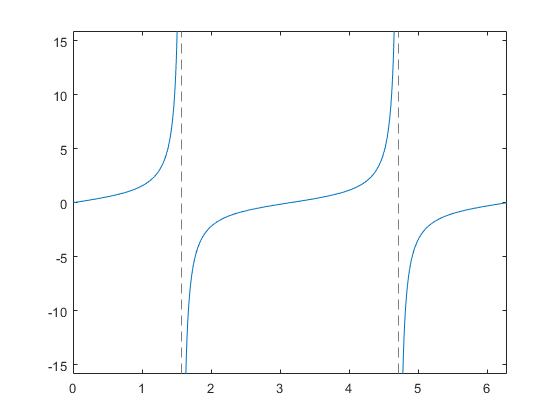

figure
fplot(tan(x), double([0, 2 * pi]))

limit(tan(x), x, sym('pi')/2, 'right')

$$ans = \frac{\sin\left(\frac{\pi }{2}\right)}{\cos\left(\frac{\pi }{2}\right)}$$

## **Defining functions and using these definitions.**

clear all;

syms x y
f = y^2 + 4 * x + 6 * x^2 + 4 * x^3 + x^4

$$f = x^{4}+4\,x^{3}+6\,x^{2}+4\,x+y^{2}$$

You can now use f:

diff(f, x)

$$ans = 4\,x^{3}+12\,x^{2}+12\,x+4$$

diff(f, y)

$$ans = 2\,y$$

diff(diff(diff(f, x), x), x) 

$$ans = 24\,x+24$$

diff(f, x, x, x)

$$ans = 24\,x+24$$

You can compute integrals using int

f

$$f = x^{4}+4\,x^{3}+6\,x^{2}+4\,x+y^{2}$$

Generate a definite integral:

int(f, x, sym(0), sym(1))

$$ans = y^{2}+\frac{26}{5}$$

Generate an indefinite integral without specifying the bounds:

int(f, x)

$$ans = \frac{x^{5}}{5}+x^{4}+2\,x^{3}+2\,x^{2}+x\,y^{2}$$

It may not be possible to reduce the expression to elementary functions.

f = int(1/(exp(x^2) + 1), x)

$$f = \int \frac{1}{{\mathrm{e}}^{x^{2}}+1}\mathrm{d}x$$

But the differentiator recognizes that its derivative is the integrand:

diff(f, x)

$$ans = \frac{1}{{\mathrm{e}}^{x^{2}}+1}$$

Definite integrals may also be returned "unreduced"/"unsimplified"

int(1/(exp(x^2) + 1), x, sym(0), sym(1))

$$ans = \int_{0}^{1}\frac{1}{{\mathrm{e}}^{x^{2}}+1}\mathrm{d}x$$

You can force calculation of a numerical value:

vpa(ans)

$$ans = 0.41946648000669070543604493521158$$

## **Plotting**

You can specify the x axis range. https://www.mathworks.com/help/symbolic/fplot.html

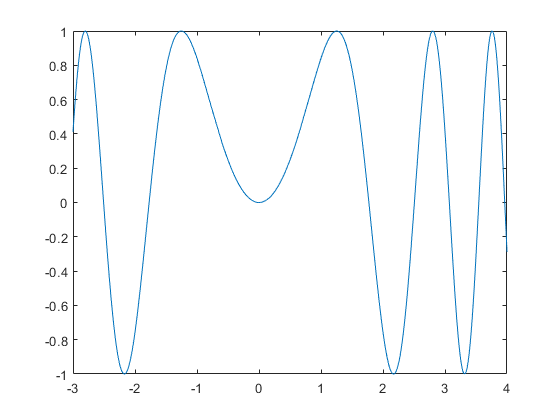

figure
fplot(sin(x^2), [-3, 4])

Plotting more than one function

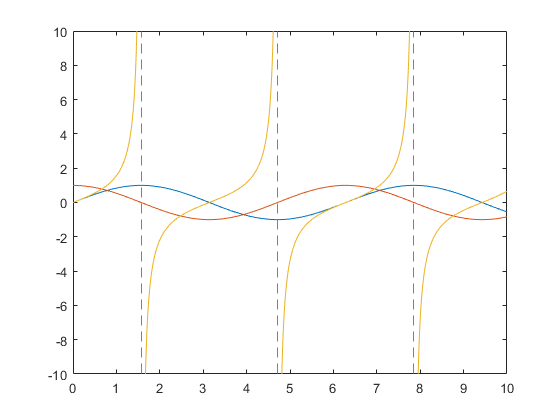

fplot(sin(x), [0, 10])
hold on
fplot(cos(x), [0, 10])
fplot(tan(x), [0, 10])
hold off

## 'Color', [1.0, 0.0, 0.0]  (R,G,B)

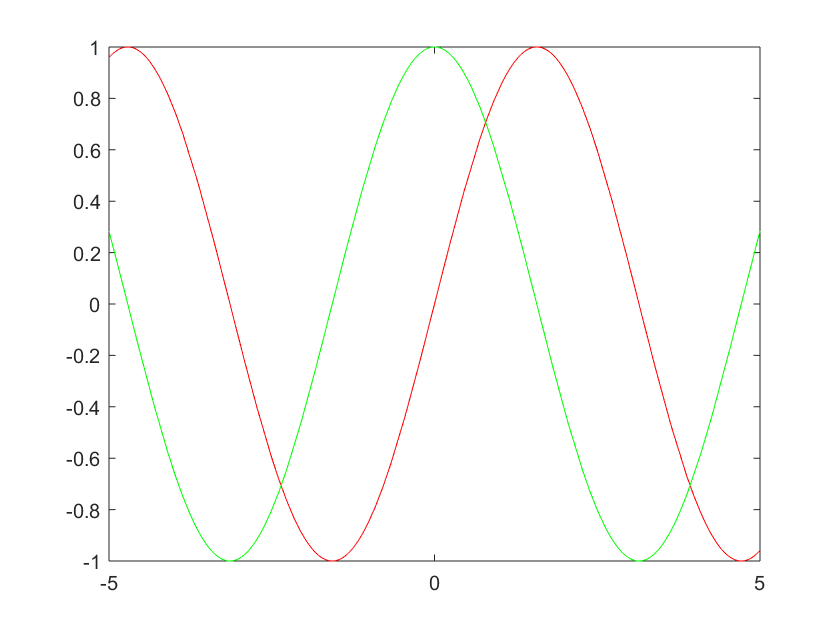

figure

fplot(sin(x), 'Color', [1.0, 0.0, 0.0])
hold on
fplot(cos(x), 'Color', [0.0, 1.0, 0.0])
hold off

Use #3D parameter for 3D plots. https://www.mathworks.com/help/matlab/ref/fsurf.html?searchHighlight=fsurf&s_tid=doc_srchtitle

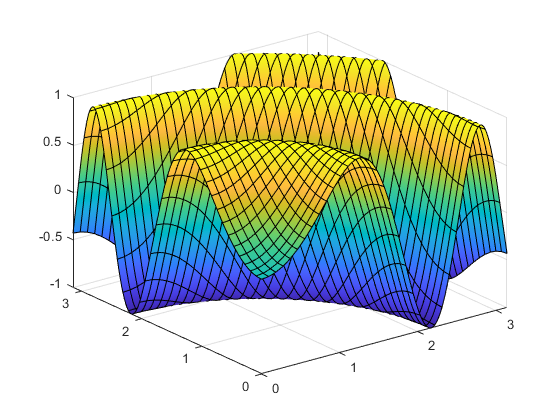

figure
fsurf(symfun(sin(x^2 + y^2), [x, y]), [double([0, pi]), double([0, pi])])

## **Replacing terms using subs**

syms a b c x
f = a * x^2 + b * x + c

$$f = a\,x^{2}+b\,x+c$$

Use subs to replace a coefficient with a value.

g = subs(f, {a, b, c}, {sym(4), sym(5), sym(-9)})

$$g = 4\,x^{2}+5\,x-9$$

## **Solving an equation**

If you don't tell which variables to solve for, it'll guess.

solve(x^2 - 2 * x + 2 == sym(0))

$$ans = \left(\begin{array}{c} 1-\mathrm{i}\\ 1+\mathrm{i} \end{array}\right)$$


solve(x^2 - 2 * x + 2 == sym(0), x)

$$ans = \left(\begin{array}{c} 1-\mathrm{i}\\ 1+\mathrm{i} \end{array}\right)$$

You can extract individual entries from the set of solutions.

sol = solve(x^2 - 2 * x + 2 == sym(0), x)

$$sol = \left(\begin{array}{c} 1-\mathrm{i}\\ 1+\mathrm{i} \end{array}\right)$$


sol(1)

$$ans = 1-\mathrm{i}$$


sol(2)

$$ans = 1+\mathrm{i}$$

The roots can be real & complex.

solve(x^4 + x^3 - x == sym(1), x)

$$ans = \left(\begin{array}{c} -1\\ 1\\ -\frac{1}{2}-\frac{\sqrt{3}\,\mathrm{i}}{2}\\ -\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2} \end{array}\right)$$

You can omit any non-real solutions:

solve(x^4 + x^3 - x == sym(1), x, 'Real', true)

$$ans = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

Ignore unlikely edge cases with the IgnoreAnalyticConstraints option.

Apply purely algebraic simplifications to expressions and equations. Setting `IgnoreAnalyticConstraints` to `true` can give you simple solutions for the equations for which the direct use of the solver returns complicated results. In some cases, it also enables `solve` to solve equations and systems that cannot be solved otherwise. However, setting `IgnoreAnalyticConstraints` to `true` can lead to wrong or incomplete results.

solve(log(y) + log(x + 1) == sym(1), y, 'IgnoreAnalyticConstraints', true)

$$ans = \frac{\mathrm{e}}{x+1}$$

solve(log(y) + log(x + 1) == sym(1), y, 'ReturnConditions', true)

ans = struct with fields:
             y: [1×1 sym]
    parameters: [1×0 sym]
    conditions: [1×1 sym]

Sometimes there are infinite number of solutions:

solve(sin(x) == sym(1), x)

$$ans = \frac{\pi }{2}$$

To get only the "main" solution from the set, you can use the PrincipalValue option:

solve(sin(x) == sym(1), x, 'PrincipalValue', true)

$$ans = \frac{\pi }{2}$$

If you don't know which Ignore... to use, try to use all. :)  Return only main real solutions

solve(sin(x) == sym(1), x, 'Real', true, 'PrincipalValue', true, 'IgnoreAnalyticConstraints', true)

$$ans = \frac{\pi }{2}$$

## **Solving systems of equations**

The solve function can also be used to solve systems of equations. Simply specify the system of equations and the variables to solve for.


syms x y a b clear

equations = unique([x + y == a, x - a * y == b])

$$equations = \left(\begin{array}{cc} x+y=a & x-a\,y=b \end{array}\right)$$


unknowns = unique([x, y])

$$unknowns = \left(\begin{array}{cc} x & y \end{array}\right)$$


solve(equations, unknowns)

ans = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


sol = solve(equations, unknowns)

sol = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]

sol.x

$$ans = \frac{a^{2}+b}{a+1}$$

sol.y

$$ans = \frac{a-b}{a+1}$$

## **Working with matrices**

Commas are non-optional. No semicolon convenience to move to next row.

The outer-most [ ] is for column vector. Every [ ] inside creates a row vector.

a = [sym(1), x]

$$a = \left(\begin{array}{cc} 1 & x \end{array}\right)$$


b = [sym(1); x]

$$b = \left(\begin{array}{c} 1\\ x \end{array}\right)$$

There is an alternative way to write a matrix, giving a linear vector of its elements and specifying its size. 

A = reshape([sym(1); sym(2); sym(3); sym(4); sym(5); sym(6)], 2, 3)

$$A = \left(\begin{array}{ccc} 1 & 3 & 5\\ 2 & 4 & 6 \end{array}\right)$$

sym(reshape([1;2;3;4;5;6], 2, 3))

$$ans = \left(\begin{array}{ccc} 1 & 3 & 5\\ 2 & 4 & 6 \end{array}\right)$$


syms a clear

A = [sym(1), sym(2); a, sym(4)]

$$A = \left(\begin{array}{cc} 1 & 2\\ a & 4 \end{array}\right)$$


syms z
B = [y, sym(3); z, sym(5)]

$$B = \left(\begin{array}{cc} y & 3\\ z & 5 \end{array}\right)$$

Cell array

{A, B, A + B, A * B}

ans = 1×4 cell array
    {2×2 sym}    {2×2 sym}    {2×2 sym}    {2×2 sym}


A^(-1)

$$ans = \left(\begin{array}{cc} -\frac{2}{a-2} & \frac{1}{a-2}\\ \frac{a}{2\,\left(a-2\right)} & -\frac{1}{2\,\left(a-2\right)} \end{array}\right)$$


subs(A^(-1), a, vpa('0.5'))

$$ans = \left(\begin{array}{cc} 1.3333333333333333333333333333333 & -0.66666666666666666666666666666667\\ -0.16666666666666666666666666666667 & 0.33333333333333333333333333333333 \end{array}\right)$$

Most functions (solve, diff, etc.) are available on the path. Some functions are available as part of a "package". e.g., the determinant function is available under the linalg package:  

%Matrix determinant 
det(A)

$$ans = 4-2\,a$$

## **Solving system of equations in a matrix form.**

In some cases, you may be able to express the system of equations in matrix form, .For these cases, you can use the linalg::matlinsolve function to solve the equations.

A = reshape([sym(1); sym(2); sym(3); sym(4)], 2, 2)

$$A = \left(\begin{array}{cc} 1 & 3\\ 2 & 4 \end{array}\right)$$

b = reshape([sym(5); sym(6)], 2, 1)

$$b = \left(\begin{array}{c} 5\\ 6 \end{array}\right)$$

A*x

$$ans = \left(\begin{array}{cc} x & 2\,x\\ a\,x & 4\,x \end{array}\right)$$

Let's solve Ax = b for x:  

null(A), Null space of matrix. The null space of a matrix contains vectors  that satisfy Ax=0. 

aux10 = {linsolve(A, b), null(A)}

aux10 = 1×2 cell array
    {2×1 sym}    {2×0 sym}

null(A)

ans =
Empty sym: 2-by-0


% If the solution has an epty null space -> it is unique??
if isempty(aux10{2})
  aux10 = aux10{1};
end
x = aux10

$$x = \left(\begin{array}{c} -1\\ 2 \end{array}\right)$$

Let's check if the answer is correct.

A * x

$$ans = \left(\begin{array}{c} 5\\ 6 \end{array}\right)$$

## **Solving Ordinary Differential Equations (ODEs)**

You can solve various types of ordinary differential equations using the standard solve function (i.e. the same function that is used to solve algebraic equations) or the ode::solve function. If you use the standard dsolve function, you must first define your equation as an ODE. The same underlying algorithm is used regardless of which approach you choose.

Create symbolic functions with symfun

`f(inputs) = formula`

`f =` `symfun``(formula,inputs)`

You can solve a simple 2nd order linear ODE using the standard solve function.

syms y_1(t)
aux11 = diff(y_1(t), t, 2) + diff(y_1(t), t) + y_1(t) == sym(0);
eqn = symfun(aux11, symvar(y_1(t)))

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}y_{1}\left(t\right)+\frac{\partial }{\partial t}y_{1}\left(t\right)+y_{1}\left(t\right)=0$$

syms y_1(t) t
eqn(t) = diff(y_1(t), t, 2) + diff(y_1(t), t) + y_1(t) == 0

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}y_{1}\left(t\right)+\frac{\partial }{\partial t}y_{1}\left(t\right)+y_{1}\left(t\right)=0$$

dsolve(eqn)

$$ans = C_{1}\,{\mathrm{e}}^{-\frac{t}{2}}\,\cos\left(\frac{\sqrt{3}\,t}{2}\right)-C_{2}\,{\mathrm{e}}^{-\frac{t}{2}}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)$$

You can solve the same equation using the ode::solve function, which does not require you to declare the equation as an ODE.

aux12 = diff(y_1(t), t, 2) + diff(y_1(t), t) + y_1(t) == sym(0);
dsolve(symfun(aux12, symvar(y_1(t))))

$$ans = C_{1}\,{\mathrm{e}}^{-\frac{t}{2}}\,\cos\left(\frac{\sqrt{3}\,t}{2}\right)-C_{2}\,{\mathrm{e}}^{-\frac{t}{2}}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)$$

You can specify initial conditions and boundary conditions along with an ODE, which is often critical for real world problems in engineering and physics.

aux13 = unique([diff(y_1(t), t, 2) == (2 * t)/diff(y_1(t), t), y_1(sym(0)) == sym(0), subs(diff(y_1(t), t), t, sym(0)) == sym(1)]);
aux13

$$aux13 = \left(\begin{array}{ccc} \frac{\partial^{2}}{\partial t^{2}}y_{1}\left(t\right)=\frac{2\,t}{\frac{\partial }{\partial t}y_{1}\left(t\right)} & y_{1}\left(0\right)=0 & \left({\left(\frac{\partial }{\partial t}y_{1}\left(t\right)\right)|}_{t=0}\right)=1 \end{array}\right)$$

aux13 = [diff(y_1(t), t, 2) == (2 * t)/diff(y_1(t), t), y_1(sym(0)) == sym(0), subs(diff(y_1(t), t), t, sym(0)) == sym(1)]

$$aux13 = \left(\begin{array}{ccc} \frac{\partial^{2}}{\partial t^{2}}y_{1}\left(t\right)=\frac{2\,t}{\frac{\partial }{\partial t}y_{1}\left(t\right)} & y_{1}\left(0\right)=0 & \left({\left(\frac{\partial }{\partial t}y_{1}\left(t\right)\right)|}_{t=0}\right)=1 \end{array}\right)$$

f = dsolve(symfun(aux13, symvar(y_1(t))))

$$f = \frac{\sqrt{2}\,\log\left(t+\sqrt{t^{2}+\frac{1}{2}}\right)}{4}-\frac{\sqrt{2}\,\log\left(\frac{\sqrt{2}}{2}\right)}{4}+\frac{\sqrt{2}\,t\,\sqrt{t^{2}+\frac{1}{2}}}{2}$$

f(1)

$$ans = \frac{\sqrt{2}\,\log\left(t+\sqrt{t^{2}+\frac{1}{2}}\right)}{4}-\frac{\sqrt{2}\,\log\left(\frac{\sqrt{2}}{2}\right)}{4}+\frac{\sqrt{2}\,t\,\sqrt{t^{2}+\frac{1}{2}}}{2}$$

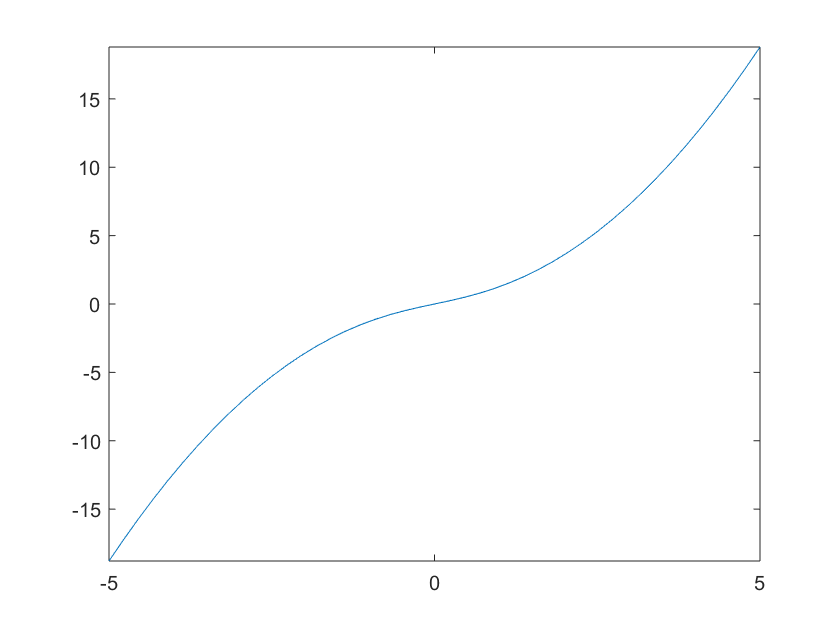

figure
fplot(f(1))

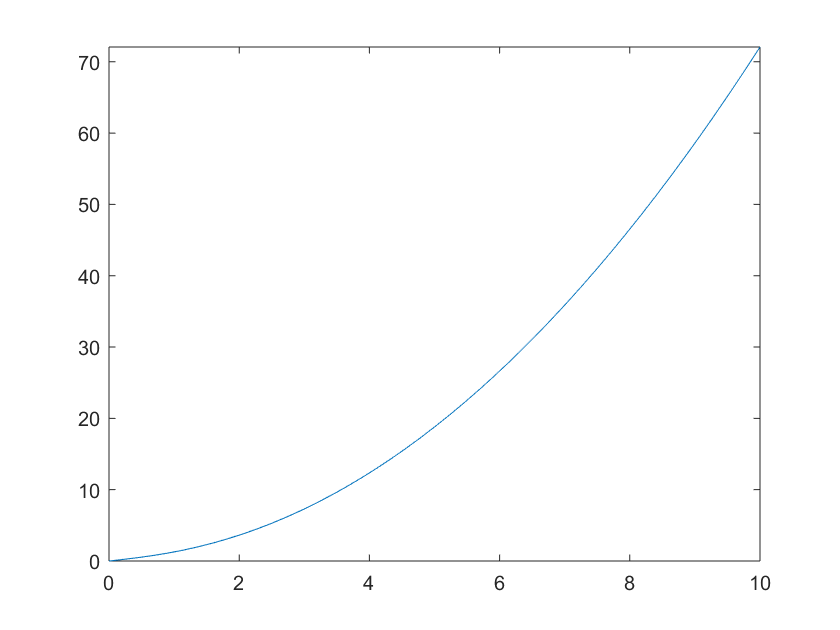

figure
fplot(f(1), [0, 10])

---

Parts of this tutorial adapted from: adapted from: [http://www.calvin.edu/~tmk5/research/mupad_tutorial.pdf](http://www.calvin.edu/~tmk5/research/mupad_tutorial.pdf)